# Linear oscillator vs. true pendulum

The linear oscillator $y''+y=0$ has perfect sinusoidal motion with period 1. The true pendulum, $y''+\sin(y)=0$, has a smaller restoring force, hence a longer period. The discrepancy grows with the amplitude. 

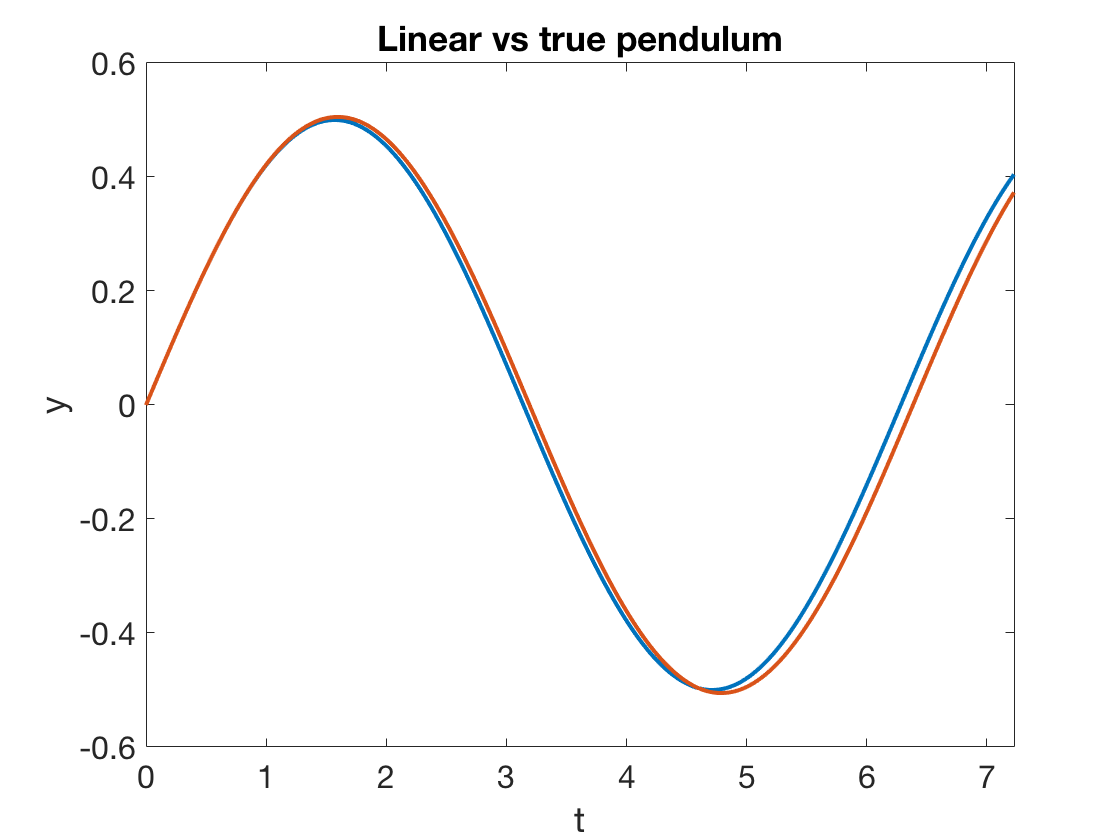

addpath ~/Dropbox/working/chebfun
d = [0 2.3*pi];
linosc = chebop(@(y) diff(y,2) + y,d,[0 0],[]);
pend = chebop(@(y) diff(y,2) + sin(y),d,[0 0],[]);
clf
linosc.lbc = [ 0 0.5 ];
pend.lbc = [ 0 0.5 ];
plot([linosc\0,pend\0])
xlabel t, ylabel y
title('Linear vs true pendulum')

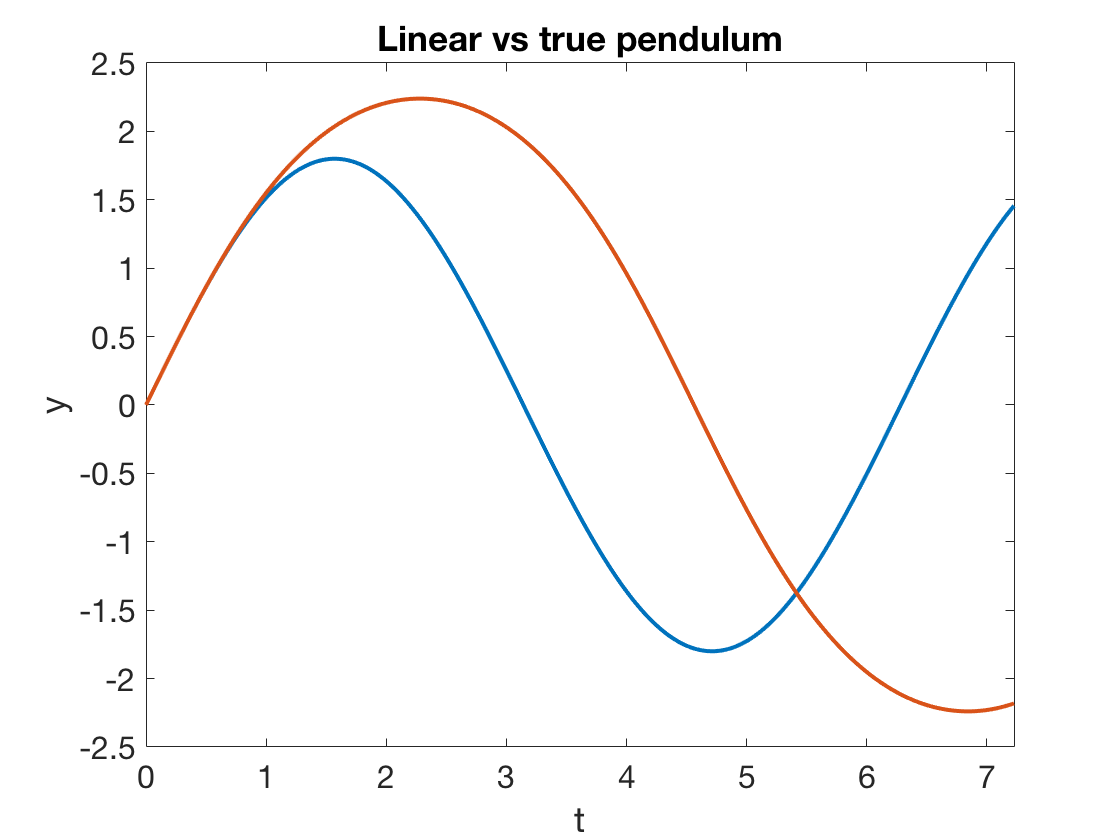

clf
linosc.lbc = [ 0 1.8 ];
pend.lbc = [ 0 1.8 ];
plot([linosc\0,pend\0])
xlabel t, ylabel y
title('Linear vs true pendulum')

The pictures in the phase plane can be more dramatic. For the linear oscillator, everything is very simple.

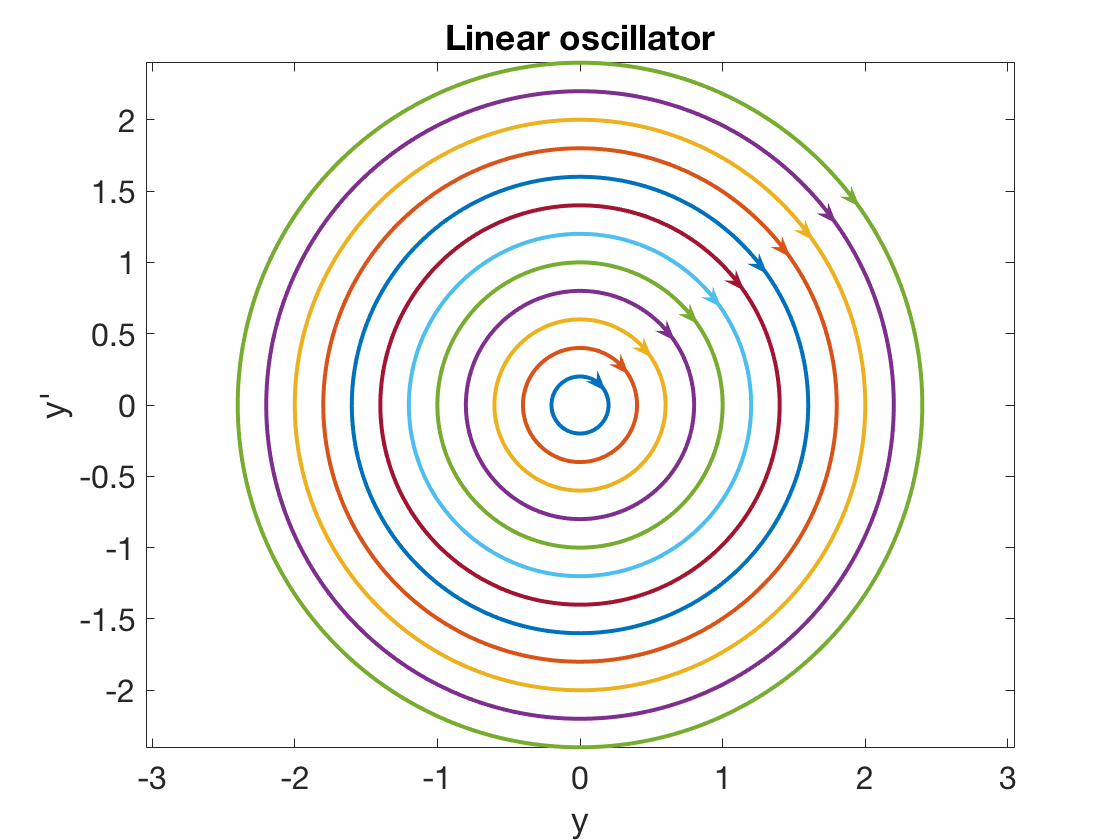

clf
for v0 = 0.2:.2:2.4
    linosc.lbc = [ 0 v0 ];
    y = linosc\0;
    arrowplot(y,diff(y))
    hold on
end
axis equal
xlabel('y'), ylabel('y''')
title('Linear oscillator')

For the true pendulum, small amplitudes are pretty much the same, but things are more interesting as the amplitude grows.

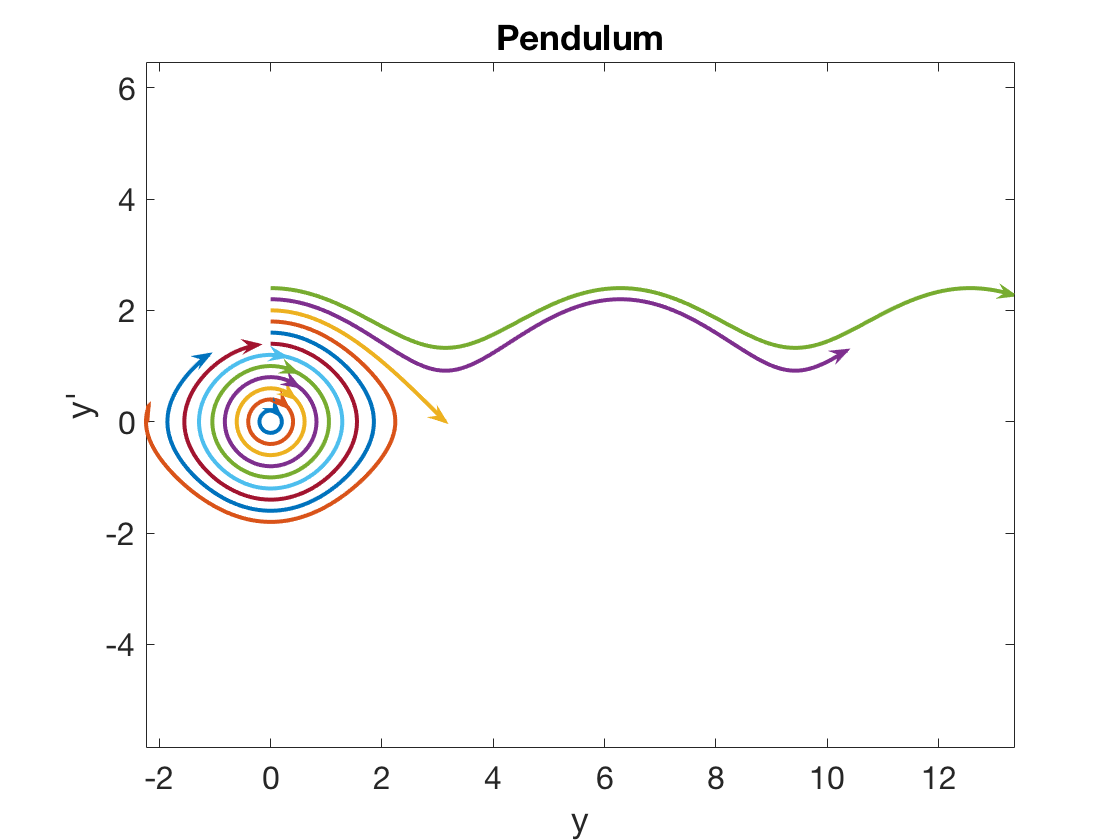

for v0 = 0.2:.2:2.4
    pend.lbc = [ 0 v0 ];
    y = pend\0;
    arrowplot(y,diff(y))
    hold on
end
axis equal
xlabel('y'), ylabel('y''')
title('Pendulum')

Naturally, damping changes the picture, ensuring that all trajectories eventually come to rest (since there is no forcing). 

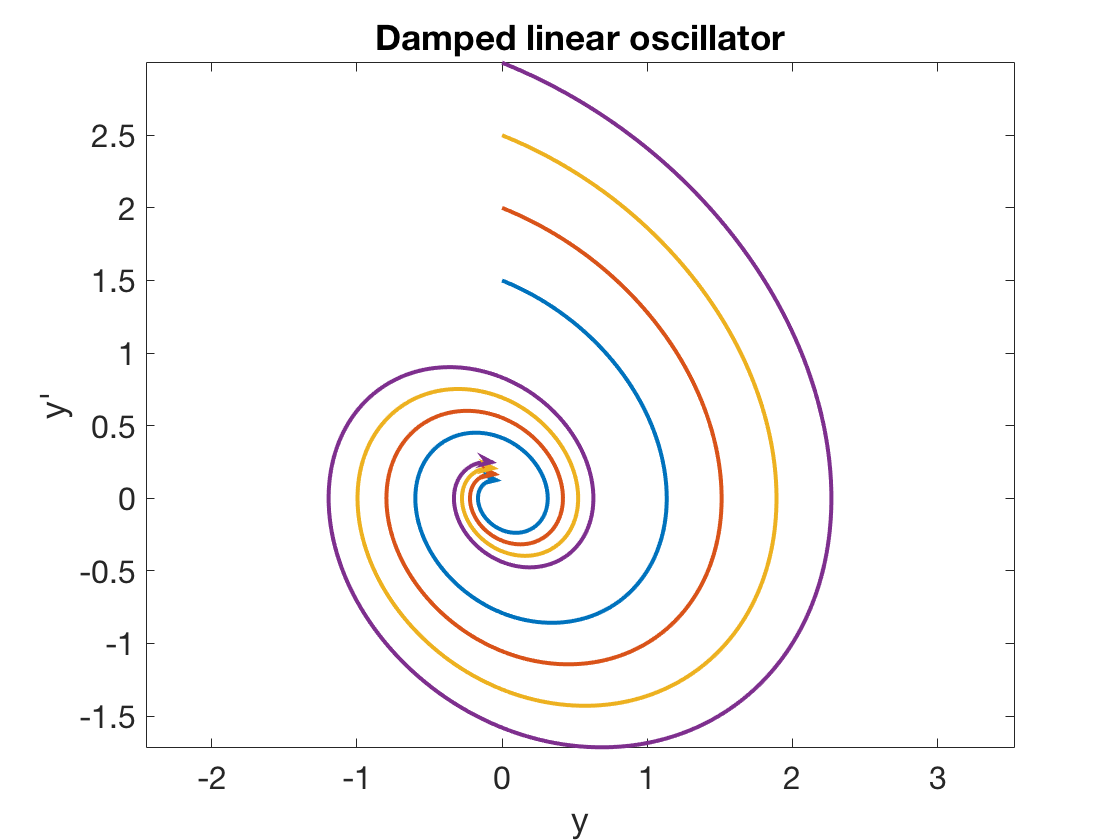

clf
d = [0 4*pi];
linosc = chebop(@(y) diff(y,2) + 0.4*diff(y) + y,d,[0 0],[]);
for v0 = 1.5:.5:3
    linosc.lbc = [ 0 v0 ];
    y = linosc\0;
    arrowplot(y,diff(y))
    hold on
end
axis equal
xlabel('y'), ylabel('y''')
title('Damped linear oscillator')

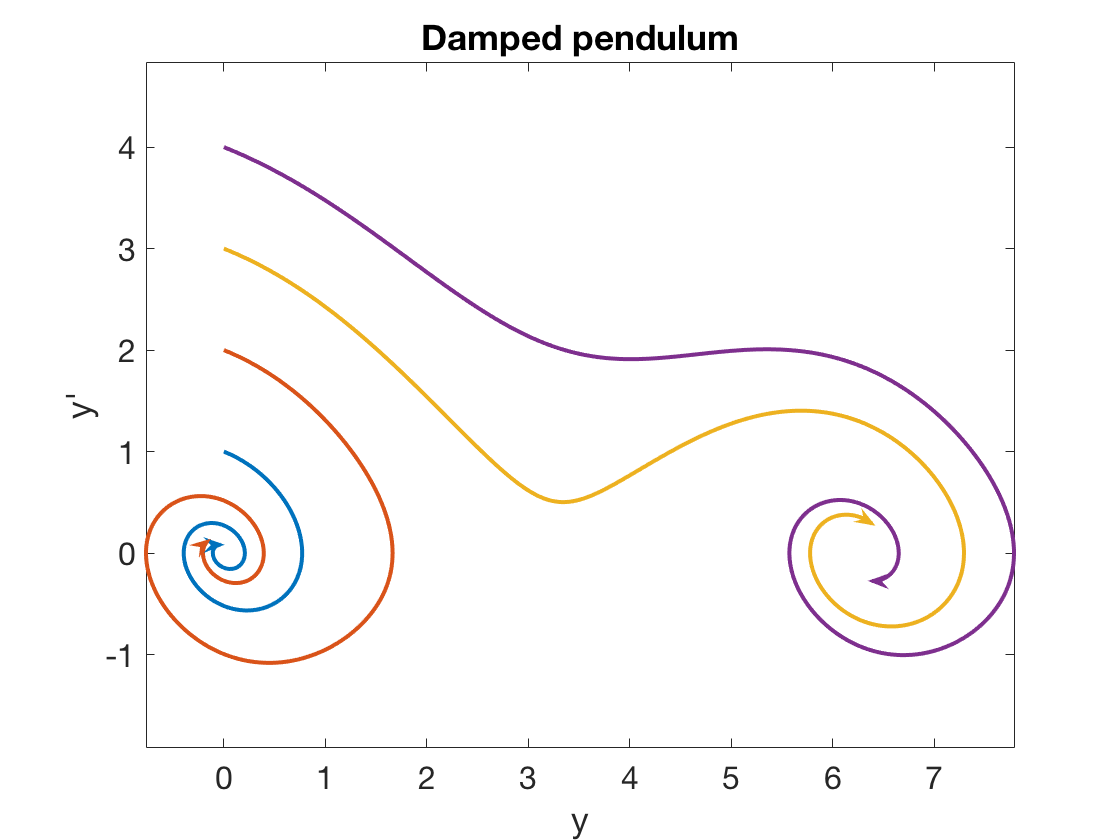

clf
d = [0 4*pi];
pend = chebop(@(y) diff(y,2) + 0.4*diff(y) + sin(y),d,[0 0],[]);
for v0 = 1:4
    pend.lbc = [ 0 v0 ];
    y = pend\0;
    arrowplot(y,diff(y))
    hold on
end
axis equal
xlabel('y'), ylabel('y''')
title('Damped pendulum')